# **FSK Mod and Demod with AWGN (Assignment 4)**

## **Testing and Putting Things Together**

#### **Testing Signal**

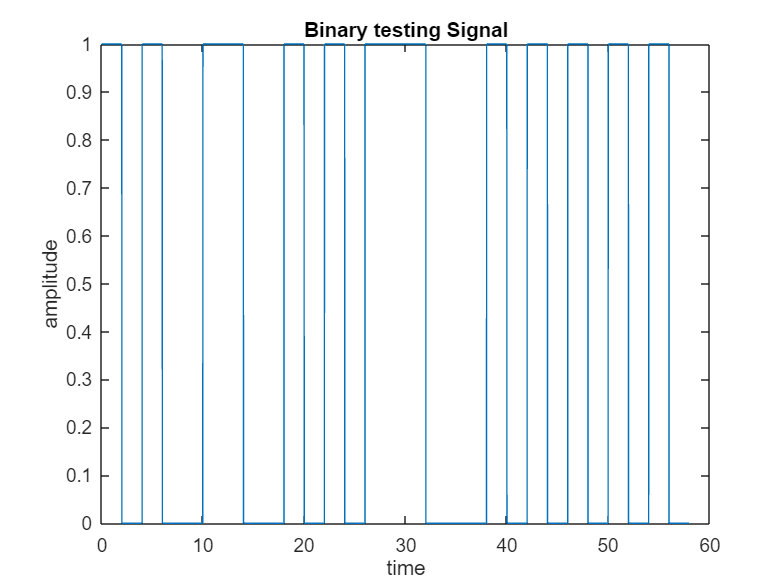

% Testing Signal
b= [1 0 1 0 0 1 1 0 0 1 0 1 0 1 1 1 0 0 0 1 0 1 0 1 0 1 0 1 0];
L=length(b);
Tb=2;
dt=0.001;
tt= 0:dt:L*Tb;
tb = 0:dt:Tb;
tb(end)=[];

sig_test=unipolarNRZ(b,Tb,dt,L); %local function, at the end of the file..

figure(1)
plot(tt,sig_test)
title('Binary testing Signal')
xlabel('time')
ylabel('amplitude')

Perform Modulation

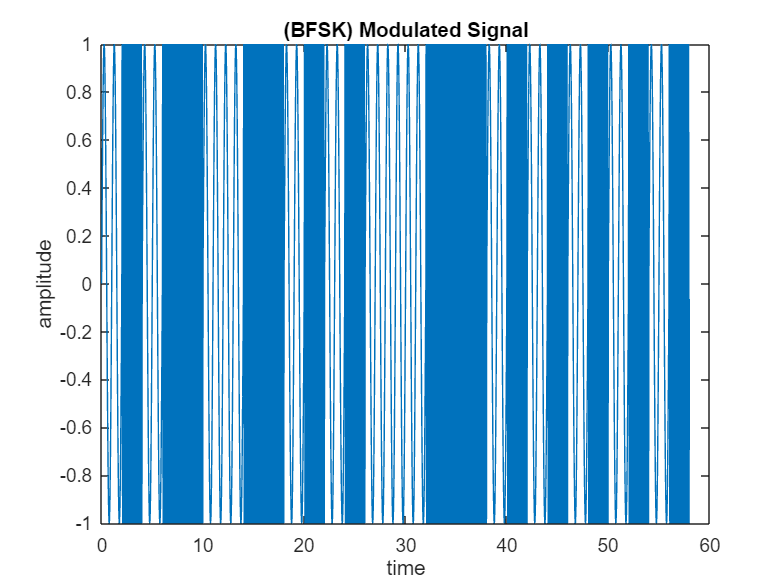

% Modulation
f1=1;
f2=10;
[modulated,p1_signals,p2_signals]= FSK_Mod(b,Tb,1,dt,f1,f2);
figure(2)
plot(tt,modulated);
title('(BFSK) Modulated Signal')
xlabel('time')
ylabel('amplitude')

Adding Noise to Signal

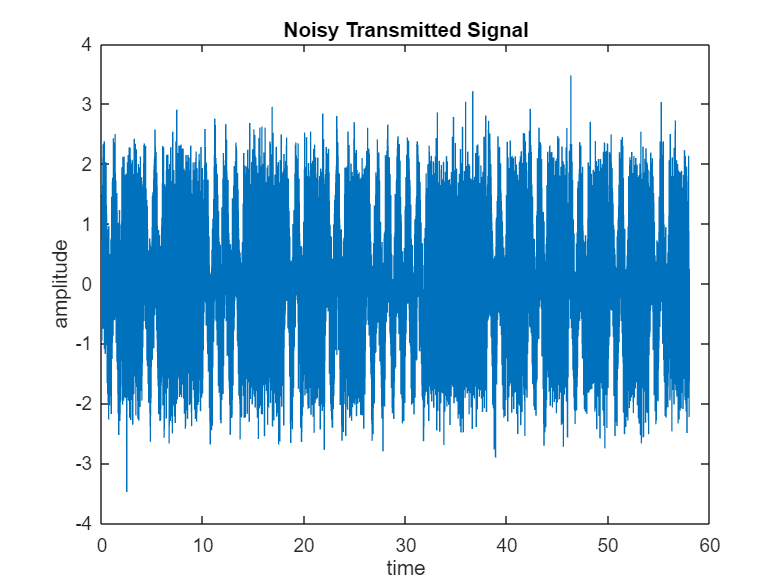

snr=5;
noisy_signal= awgn(modulated,snr);
figure(3)
plot(tt,noisy_signal)
title('Noisy Transmitted Signal')
xlabel('time')
ylabel('amplitude')

Demodulation

A=sqrt(2/Tb);
demodulated= FSK_demod(noisy_signal,f1,f2,L,A,tb)

demodulated =      1     0     1     0     0     1     1     0     0     1     0     1     0     1     1     1     0     0     0     1     0     1     0     1     0     1     0     1     0


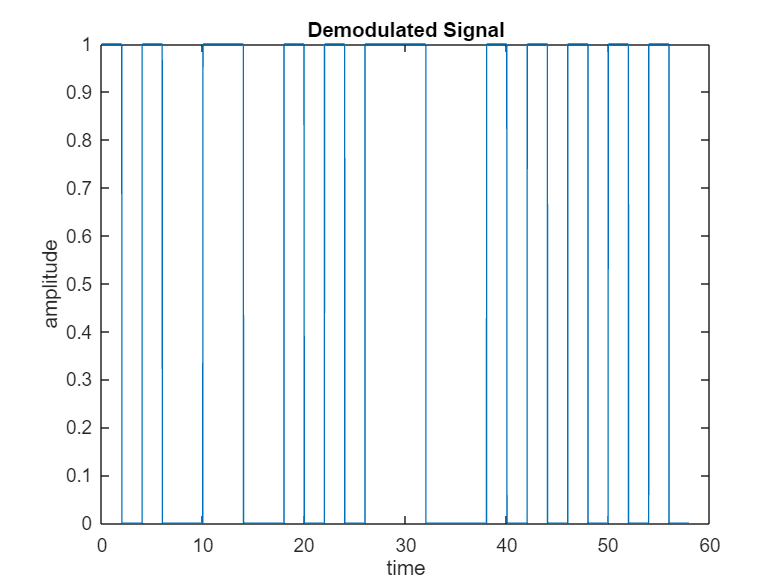

sig_demod= unipolarNRZ(demodulated,Tb,dt,L);
figure(4)
plot(tt,sig_demod)
title('Demodulated Signal')
xlabel('time')
ylabel('amplitude')

Add all to one plot for comarison

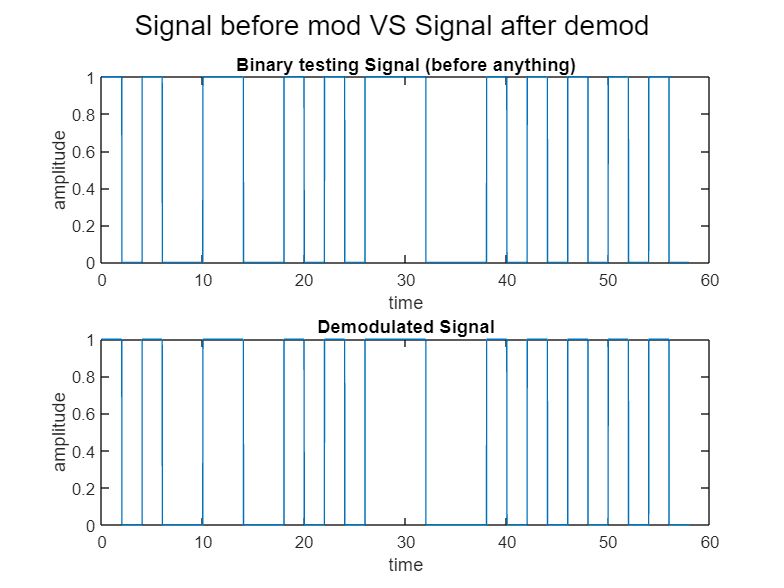

figure(5)
subplot(2,1,1)
plot(tt,sig_test)
title('Binary testing Signal (before anything)')
xlabel('time')
ylabel('amplitude')
subplot(2,1,2)
plot(tt,sig_demod)
title('Demodulated Signal')
xlabel('time')
ylabel('amplitude')

sgtitle('Signal before mod VS Signal after demod')

Test Multiple times with different noise values

% snrs= [10 5 1 0.5 0.05];
% for i=1:length(snrs)
%     noisy_signal= awgn(modulated,snr);
%     demodulated= FSK_demod(noisy_signal,f1,f2,L,A,tb);
%     sig_out= unipolarNRZ(demodulated,Tb,dt,L);
%     figure(6)
%     subplot(5,1,i)
%     plot(tt,sig_out)
%     title(sprintf('Demod Signal at SNR= %f',snrs(i)))
%     xlabel('time')
%     ylabel('amplitude')
% end
% % sgtitle('Demod Signals at Different Noise Values')
% disp('Comment: FSK is Significantly High Immunie to Noise!')

### **Comment: FSK is Significantly High Immunie to Noise!**

**PSD**

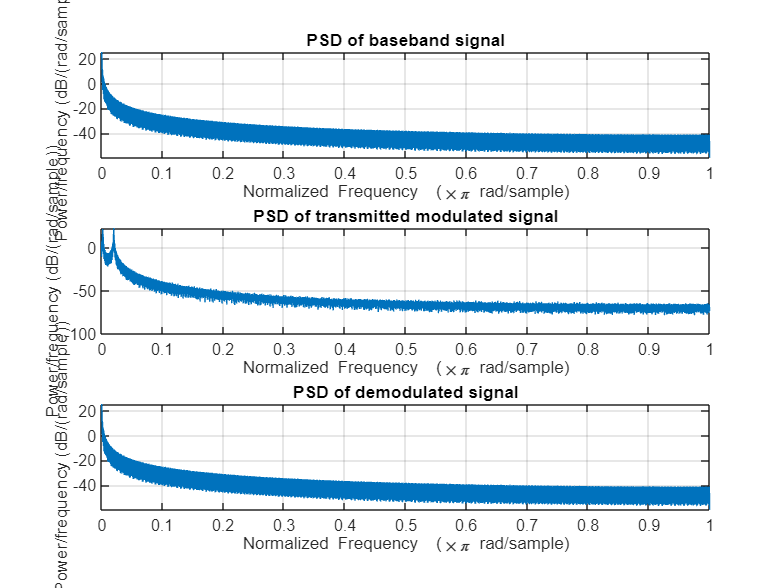

% constDiagram(noisy_signal)
% sps=2
% scatterplot(modulated,sps)
figure()
subplot(3,1,1)
pwelch(sig_test,[],[],[],'psd')
title('PSD of baseband signal')
subplot(3,1,2)
pwelch(modulated,[],[],[],'psd')
title('PSD of transmitted modulated signal')
subplot(3,1,3)
pwelch(sig_demod,[],[],[],'psd')
title('PSD of demodulated signal')

### Constellation

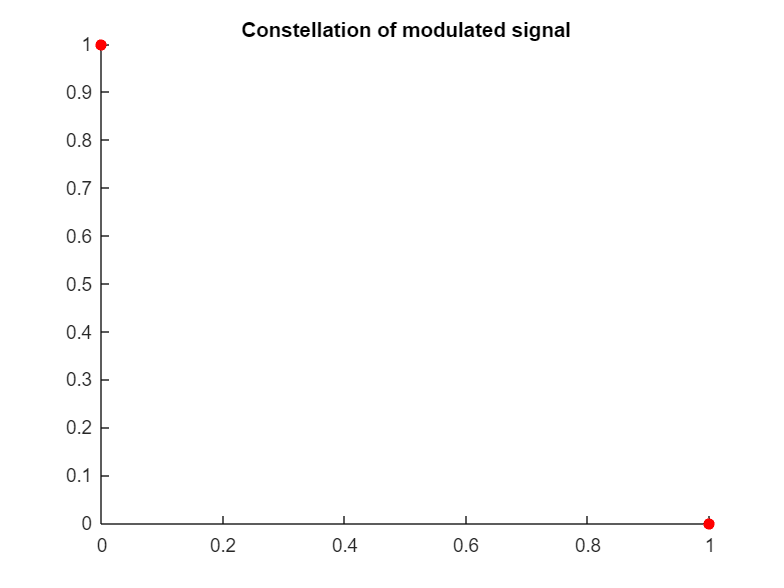

% This is BFSK, so two basis, two signals, same amplitude 

% first one
figure()
scatter([0,A] , [A,0],'red','filled');
title('Constellation of modulated signal')


% p1_con = [ones(1,length(p1_signals)) zeros(1,length(p2_signals))] ;
% p1_sig= unipolarNRZ(p1_con,Tb,dt,length(p1_con))
% p2_con = ones(1,length(p2_signals));
% p2_sig= unipolarNRZ(p2_con,Tb,dt,length(p2_con))
% if length(p1_sig)<length(p2_sig)
%     p1_sig=[p1_sig p1_sig(end)*ones(1,length(p2_sig)-length(p1_sig))];
%     
% else
%     p2_sig=[p2_sig p2_sig(end)*ones(1,length(p1_sig)-length(p2_sig))];
% end
p1=[ones(1,length(p1_signals)/2) zeros(1,length(p1_signals)/2)];
p1_sig= unipolarNRZ(p1,Tb,dt,length(p1));
p2=[zeros(1,length(p1_signals)/2) ones(1,length(p1_signals)/2)];
p2_sig= unipolarNRZ(p2,Tb,dt,length(p2));
figure()
snr=20

snr = 20

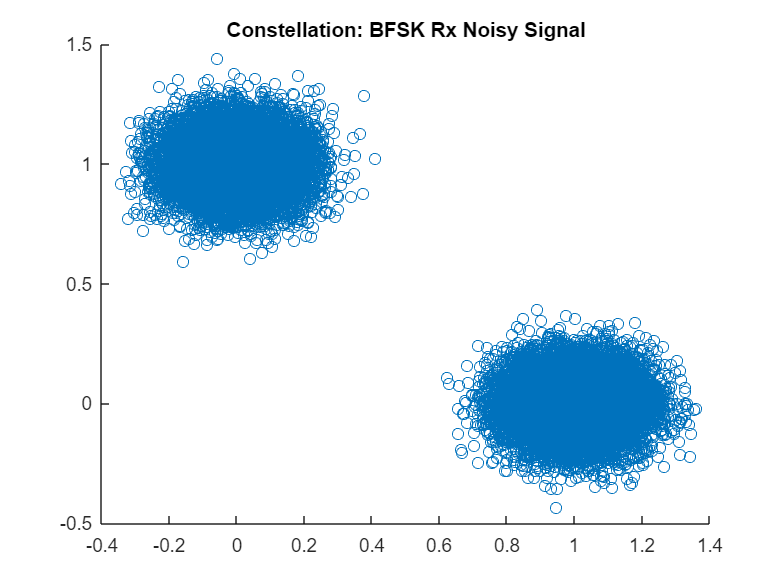

scatter(awgn(p1_sig,snr),awgn(p2_sig,snr))
title("Constellation: BFSK Rx Noisy Signal")

PSD

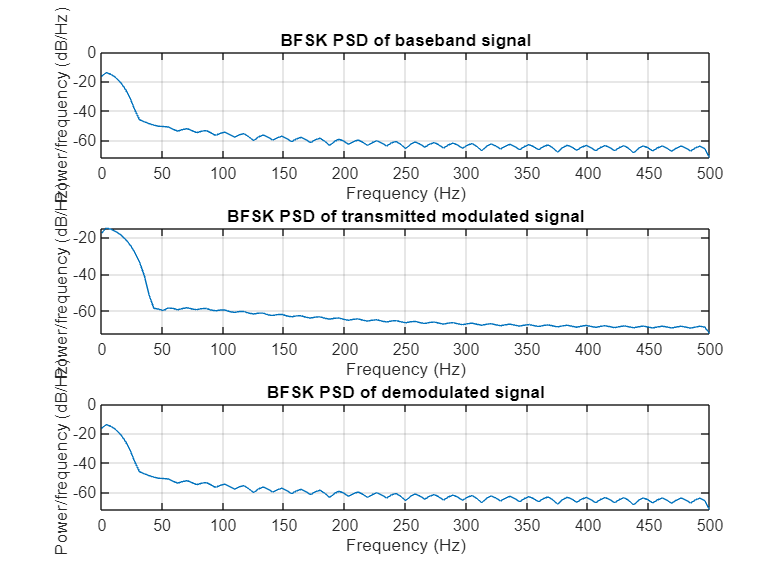

figure()
subplot(3,1,1)
h = spectrum.welch;
fs=1/dt;
Hpsd= psd(h,sig_test,'Fs',fs);
plot(Hpsd);
title('BFSK PSD of baseband signal')
subplot(3,1,2)
Hpsd= psd(h,modulated,'Fs',fs);
plot(Hpsd);
title('BFSK PSD of transmitted modulated signal')
subplot(3,1,3)
Hpsd= psd(h,sig_demod,'Fs',fs);
plot(Hpsd);
title('BFSK PSD of demodulated signal')

BER

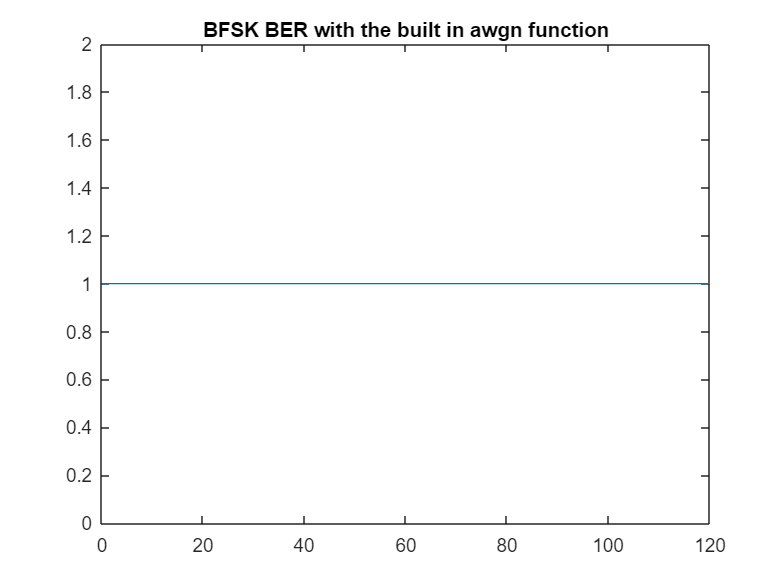

bers=[];
for i= 0:0.5:120
    snr=i;
    noisy_signal= awgn(modulated,snr);
    demodulated= FSK_demod(noisy_signal,f1,f2,L,A,tb);
    ber= calcBER(b,demodulated);
    bers=[bers ber];
end
figure()
plot([0: 0.5:120],bers)
title('BFSK BER with the built in awgn function')

Well, this built-in 'awgn()' gives 0 error even with significantly high noise values! 

Let's try some added random noise..

bers_bfsk=[]


bers_bfsk =

     []



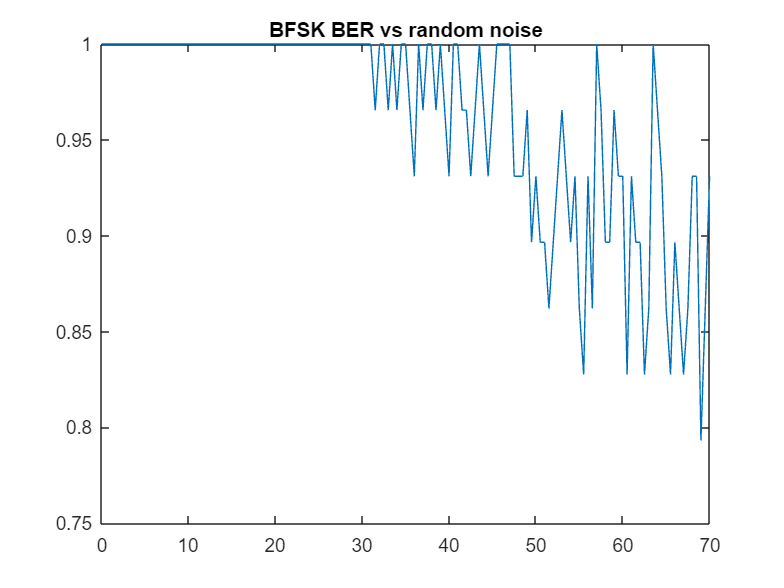

% r=rand(1,length(modulated));
difs=[];
figure()
for i= 0: 0.5:70
    
    noise= i*rand(1,length(modulated));
    noisy_signal= modulated+noise;
    demodulated= FSK_demod(noisy_signal,f1,f2,L,A,tb); 
    ber= calcBER(b,demodulated);
    difs=[difs b-demodulated];
    bers_bfsk=[bers_bfsk ber];
end
figure()
plot([0: 0.5:70],bers_bfsk)
title('BFSK BER vs random noise')

# ***16 - QAM***

***Testing Signal Gen***

% % Testing Signal
% b= [[1 0 1 1 1 0 0 1 1 1 1 0 1 1 1 1 1 0 1 0 1 0 0 0 1 1 0 0 1 1 0 1 0 0 0 1 0 0 0 0 0 1 0 0 0 1 1 0 0 0 1 1 0 0 1 0 0 1 0 1 0 1 1 1];
% L=length(b);
% Tb=2;
% dt=0.001;
% tt= 0:dt:L*Tb;
% tb = 0:dt:Tb;
% tb(end)=[];
% 
% sig_test=unipolarNRZ(b,Tb,dt,L); %local function, at the end of the file..
% 
% figure(1)
% plot(tt,sig_test)
% title('Binary testing Signal')
% xlabel('time')
% ylabel('amplitude')

***Modulation***

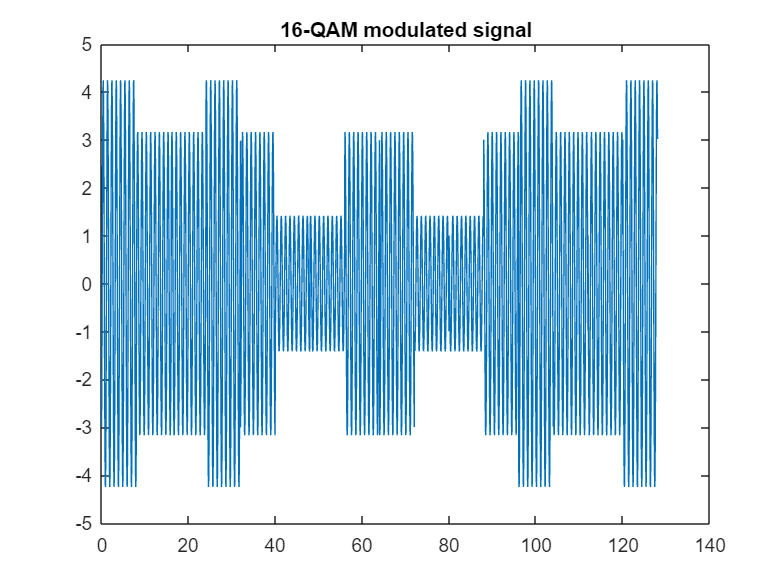

 
yqam=QAM_mod([1 0 1 1 1 0 0 1 1 1 1 0 1 1 1 1 1 0 1 0 1 0 0 0 1 1 0 0 1 1 0 1 0 0 0 1 0 0 0 0 0 1 0 0 0 1 1 0 0 0 1 1 0 0 1 0 0 1 0 1 0 1 1 1],2,0.001);
title('16-QAM modulated signal')

Function for Unipolar NRZ line-coding

function sig_uNRZ = unipolarNRZ(bitstream, Tb,dt,L)
    tb = 0:dt:Tb;
    tb(end)=[];
    zero_bit=zeros(1,length(tb));
    one_bit=ones(1,length(tb));
    sig_uNRZ=[];
    for i=1:L
        if(bitstream(i)==1)
            sig_uNRZ=[sig_uNRZ one_bit];
        else
            sig_uNRZ=[sig_uNRZ zero_bit];
        end
    end
    sig_uNRZ=[sig_uNRZ sig_uNRZ(end)];
end

Function for BER

function ber = calcBER(bits_tx, bits_rx)
    N=length(bits_tx);
%     diff=zeros(1,N);
%     for i=1:N
%         if(bits_tx(i)==bits_rx(i))
%             diff(i)=1;
%         end
%     end
    diff= sum(bits_rx==bits_tx);

    ber = diff/N;
end

FSK mod funtion

function [y_FSK,ones_ind,zeros_ind] = FSK_Mod(bit_stream,Tb,m,dt,f1,f2)
%UNTITLED Summary of this function goes here
%   Detailed explanation goes here


L= length(bit_stream);


% tt= 0:0.001:L*Tb;
tb = 0:dt:Tb;
tb(end)=[];
% Start with simple BFSK
A = sqrt(2/Tb);
% f1 = 1;
carrier_1 = A*sin(2*pi*f1*tb);
% f2 =10;
carrier_2 = A*sin(2*pi*f2*tb);
% carriers=[carrier_1 carrier_2];

y_Freqs=zeros(1,L);

ones_ind = find(bit_stream==1);
zeros_ind = find(bit_stream==0);



y_Freqs(ones_ind)=1;
y_Freqs(zeros_ind)=2;
y_FSK=[];
for i=1:L
    if y_Freqs(i)==1 
        y_FSK=[y_FSK carrier_1];
    else
        y_FSK=[y_FSK carrier_2];
    end
end

y_FSK= [y_FSK y_FSK(end)];

% plot(tt,y_FSK)


end

FSK demod

function demod_stream = FSK_demod(x_recieved, f1,f2,N_syms,A,tb)
%UNTITLED3 Summary of this function goes here
%   Detailed explanation goes here

phi1 = A*sin(2*pi*f1*tb);
phi2 = A*sin(2*pi*f2*tb);

step = 2000;
demod_stream=zeros(1,N_syms);
just_a_counter=0;
for i=1:step:length(x_recieved)
    if(just_a_counter>=N_syms)
        break;
    end
    just_a_counter=just_a_counter+1;
% Correlation with phi1 & phi2 
    x1 = sum(x_recieved(i:i+step-1).*phi1);
    x2 = sum(x_recieved(i:i+step-1).*phi2);
% Subtract 
    y = x1-x2;
% Decide 
    if(y>0)
        demod_stream(just_a_counter)=1;
    else
        demod_stream(just_a_counter)=0;
    end
end



end

QAM mod function